**Option 1 : Normaliser avec une tâche analytique prédifinie**

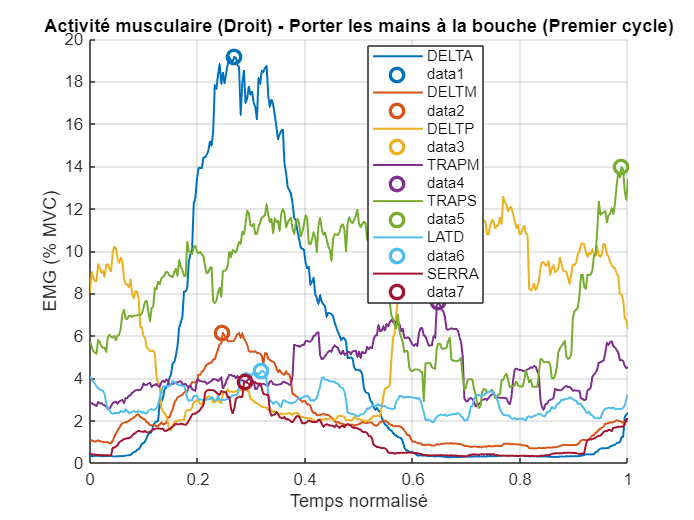

% Ajout de la bibliothèque btk  
addpath(genpath('C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\btk'));

% Définition sujet
subjects = {'MF01'};
%'MF01', 'TF02', 'YL03', 'RF05', 'AP06'
%'TD07', 'IS08', 'LC09', 'MP10', 'PK11'
%'JM13', 'GD14', 'LD15', 'LM16', 'JV18'
%'EG19', 'MG20', 'LB21', 'AP22', 'SC23'
%'TM24', 'EG25', 'RL26'
nb_subjects = length(subjects);

% Définition des muscles pour les côtés droit et gauche
muscles_R = {'RDELTA', 'RDELTM', 'RDELTP', 'RTRAPM', 'RTRAPS', 'RLATD', 'RSERRA'};
muscles_L = {'LDELTA', 'LDELTM', 'LDELTP', 'LTRAPM', 'LTRAPS', 'LLATD', 'LSERRA'};
nb_muscles = length(muscles_R);

% Demande de sélection du côté à analyser
side_choice = input('Choisissez le côté à analyser (1: Droite, 2: Gauche): ');
if side_choice == 1
    muscles_selected = muscles_R;
    side_label = 'Droit';
else
    muscles_selected = muscles_L;
    side_label = 'Gauche';
end

% Définition des labels pour les tâches
functional_labels = {... 
    'Porter les mains à la bouche', ...
    'Toucher le haut de la tête', ...
    'Porter les mains le plus haut possible au-dessus de la tête', ...
    'Porter les mains le plus haut possible le long de la colonne vertébrale'};

analytic_labels = { 
    'Flexion (élévation sagittale)', ...
    'Abduction (élévation coronale)', ...
    'Rotation externe (abduction 0°)', ...
    'Rotation interne (abduction 0°)'};

nb_functional = length(functional_labels);
nb_analytic = length(analytic_labels);

% Paramètres EMG
fs = 2000;
[b, a] = butter(4, [15, 475] / (fs/2), 'bandpass');
rms_window = round(0.250 * fs);
num_points = 1000;
time_normalized = linspace(0, 1, num_points / 3); % Seulement le premier tiers du cycle

% Nouvelle association Muscle -> Tâche Analytique définie manuellement
assigned_analytics = [1, 2, 2, 2, 2, 4, 2];

% Initialisation des MVC des tâches analytiques
mvc = zeros(nb_muscles, 1);

% Calcul du MVC basé sur la tâche analytique assignée
for subj_idx = 1:nb_subjects
    for m = 1:nb_muscles
        analytic_idx = assigned_analytics(m);  % Tâche prédéfinie
        
        fileName_analytic = sprintf(['C:\\Users\\Francalanci Hugo\\Documents\\MATLAB\\Stage Sainte-Justine\\HUG\\Sujets\\%s\\' ...
            '%s-%s-20240101-PROTOCOL01-ANALYTIC%d-.c3d'], ...
            subjects{subj_idx}, subjects{subj_idx}, subjects{subj_idx}, analytic_idx);
        
        c3dH_analytic = btkReadAcquisition(fileName_analytic);
        analogs_analytic = btkGetAnalogs(c3dH_analytic);
        
        muscle_name = muscles_selected{m};
        if isfield(analogs_analytic, muscle_name)
            signal = analogs_analytic.(muscle_name);
            signal_filtered = filtfilt(b, a, signal);
            signal_abs = abs(signal_filtered);
            emg_rms = sqrt(movmean(signal_abs.^2, rms_window));
            mvc(m) = max(emg_rms);  % Prend la valeur max de cette tâche
        end
    end
end

% Sélection d'une tâche fonctionnelle unique
selected_functional = input('Choisissez une tâche fonctionnelle (1-4): ');

% Traitement des données et affichage unique
figure;
hold on;
title(sprintf('Activité musculaire (%s) - %s (Premier cycle)', side_label, functional_labels{selected_functional}));
xlabel('Temps normalisé');
ylabel('EMG (% MVC)');

colors = lines(nb_muscles); % Couleurs différentes pour chaque muscle
peak_times = zeros(nb_muscles, 1); % Stockage des pics temporels normalisés

for subj_idx = 1:nb_subjects
    fileName_functional = sprintf(['C:\\Users\\Francalanci Hugo\\Documents\\MATLAB\\Stage Sainte-Justine\\HUG\\Sujets\\%s\\' ...
        '%s-%s-20240101-PROTOCOL01-FUNCTIONAL%d-.c3d'], ...
        subjects{subj_idx}, subjects{subj_idx}, subjects{subj_idx}, selected_functional);
    
    c3dH_functional = btkReadAcquisition(fileName_functional);
    analogs_functional = btkGetAnalogs(c3dH_functional);
    
    for m = 1:nb_muscles
        muscle_name = muscles_selected{m};
        
        if isfield(analogs_functional, muscle_name)
            % Extraction du signal 
            signal = analogs_functional.(muscle_name);
            % Filtrage Butterworth passe-bande
            signal_filtered = filtfilt(b, a, signal);
            % Rectification
            signal_abs = abs(signal_filtered);
            % Lissage par Root Mean Square
            emg_rms = sqrt(movmean(signal_abs.^2, rms_window));
            
            % Sélection du premier cycle (premier tiers du mouvement)
            cycle_length = floor(length(emg_rms) / 3);
            emg_first_cycle = emg_rms(1:cycle_length);
            
            % Normalisation du temps pour le premier cycle
            time_original = linspace(0, 1, cycle_length);
            emg_interp = interp1(time_original, emg_first_cycle, time_normalized, 'spline');

            % Normalisation par le MVC associé à la tâche prédéfinie
            emg_normalized = (emg_interp / mvc(m)) * 100;

            % Tracé du signal
            plot(time_normalized, emg_normalized, 'Color', colors(m, :), 'LineWidth', 1.2, 'DisplayName', muscle_name(2:end));
            
            % Détection du pic d'activation
            [~, peak_idx] = max(emg_normalized);
            peak_times(m) = time_normalized(peak_idx); % Stockage du temps normalisé du pic
            plot(time_normalized(peak_idx), emg_normalized(peak_idx), 'o', 'Color', colors(m, :), 'MarkerSize', 8, 'LineWidth', 2);
        end
    end
end

legend('show', 'Location', 'best');
grid on;
hold off;


% Calcul du décalage temporel
[min_time, min_idx] = min(peak_times);
fprintf('\nRéférentiel temporel : %s atteint son pic en premier à %.3f du cycle\n', muscles_selected{min_idx}(2:end), min_time);


Référentiel temporel : DELTM atteint son pic en premier à 0.247 du cycle



fprintf('\nDécalage temporel des pics d’activation musculaire (normalisé au premier cycle) :\n');


Décalage temporel des pics d’activation musculaire (normalisé au premier cycle) :


for m = 1:nb_muscles
    delay = peak_times(m) - min_time;
    fprintf('%s : +%.3f du cycle\n', muscles_selected{m}(2:end), delay);
end

DELTA : +0.021 du cycle
DELTM : +0.000 du cycle
DELTP : +0.428 du cycle
TRAPM : +0.401 du cycle
TRAPS : +0.741 du cycle
LATD : +0.072 du cycle
SERRA : +0.042 du cycle


**Option 2 : Normaliser avec le max RMS de la tâche analytique (parmis les 4)**

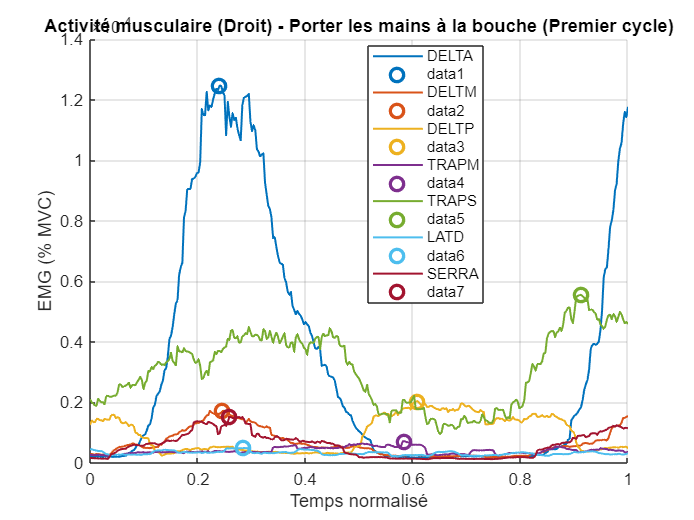

% Demande de sélection du côté à analyser
side_choice = input('Choisissez le côté à analyser (1: Droite, 2: Gauche): ');
if side_choice == 1
    muscles_selected = muscles_R;
    side_label = 'Droit';
else
    muscles_selected = muscles_L;
    side_label = 'Gauche';
end

% Définition des labels pour les tâches
functional_labels = {... 
    'Porter les mains à la bouche', ...
    'Toucher le haut de la tête', ...
    'Porter les mains le plus haut possible au-dessus de la tête', ...
    'Porter les mains le plus haut possible le long de la colonne vertébrale'};

nb_functional = length(functional_labels);

% Paramètres EMG
fs = 2000;
[b, a] = butter(4, [15, 475] / (fs/2), 'bandpass');
rms_window = round(0.250 * fs);
num_points = 1000;
time_normalized = linspace(0, 1, num_points / 3); % Seulement le premier tiers

% Sélection d'une tâche fonctionnelle unique
selected_functional = input('Choisissez une tâche fonctionnelle (1-4): ');

% Traitement des données et affichage unique
figure;
hold on;
title(sprintf('Activité musculaire (%s) - %s (Premier cycle)', side_label, functional_labels{selected_functional}));
xlabel('Temps normalisé');
ylabel('EMG (% MVC)');

colors = lines(nb_muscles); % Couleurs différentes pour chaque muscle
peak_times = zeros(nb_muscles, 1); % Stockage des pics temporels normalisés

for subj_idx = 1:nb_subjects
    fileName_functional = sprintf(['C:\\Users\\Francalanci Hugo\\Documents\\MATLAB\\Stage Sainte-Justine\\HUG\\Sujets\\%s\\' ...
        '%s-%s-20240101-PROTOCOL01-FUNCTIONAL%d-.c3d'], ...
        subjects{subj_idx}, subjects{subj_idx}, subjects{subj_idx}, selected_functional);

    c3dH_functional = btkReadAcquisition(fileName_functional);
    analogs_functional = btkGetAnalogs(c3dH_functional);

    for m = 1:nb_muscles
        muscle_name = muscles_selected{m};

        if isfield(analogs_functional, muscle_name)
            % Extraction du signal 
            signal = analogs_functional.(muscle_name);
            % Filtrage Butterworth passe-bande
            signal_filtered = filtfilt(b, a, signal);
            % Rectification
            signal_abs = abs(signal_filtered);
            % Lissage par Root Mean Square
            emg_rms = sqrt(movmean(signal_abs.^2, rms_window));

            % Sélection du premier cycle (premier tiers du mouvement)
            cycle_length = floor(length(emg_rms) / 2.7);
            emg_first_cycle = emg_rms(1:cycle_length);

            % Normalisation du temps pour le premier cycle
            time_original = linspace(0, 1, cycle_length);
            emg_interp = interp1(time_original, emg_first_cycle, time_normalized, 'spline');

            % Tracé du signal
            plot(time_normalized, emg_interp, 'Color', colors(m, :), 'LineWidth', 1.2, 'DisplayName', muscle_name(2:end));

            % Détection du pic d'activation
            [~, peak_idx] = max(emg_interp);
            peak_times(m) = time_normalized(peak_idx); % Stockage du temps normalisé du pic
            plot(time_normalized(peak_idx), emg_interp(peak_idx), 'o', 'Color', colors(m, :), 'MarkerSize', 8, 'LineWidth', 2);
        end
    end
end

legend('show', 'Location', 'best');
grid on;
hold off;


% Calcul du décalage temporel
[min_time, min_idx] = min(peak_times);
fprintf('\nRéférentiel temporel : %s atteint son pic en premier à %.3f du cycle\n', muscles_selected{min_idx}(2:end), min_time);


Référentiel temporel : DELTA atteint son pic en premier à 0.241 du cycle



fprintf('\nDécalage temporel des pics d’activation musculaire (normalisé au premier cycle) :\n');


Décalage temporel des pics d’activation musculaire (normalisé au premier cycle) :


for m = 1:nb_muscles
    delay = peak_times(m) - min_time;
    fprintf('%s : +%.3f du cycle\n', muscles_selected{m}(2:end), delay);
end

DELTA : +0.000 du cycle
DELTM : +0.006 du cycle
DELTP : +0.367 du cycle
TRAPM : +0.343 du cycle
TRAPS : +0.672 du cycle
LATD : +0.045 du cycle
SERRA : +0.018 du cycle


**Option 3 : Normaliser avec une tâche analytique prédifinie(mais en prenant la moyenne sur tous le signal)**

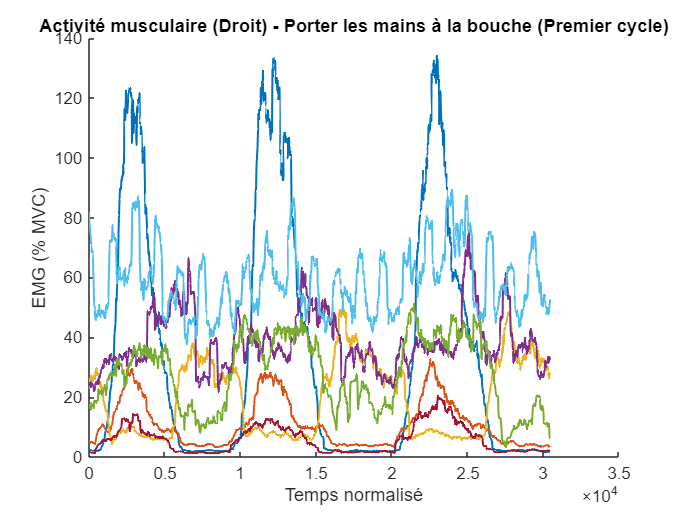

% Ajout de la bibliothèque btk  
addpath(genpath('C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\btk'));

% Définition sujet
subjects = {'MF01'};
%'MF01', 'TF02', 'YL03', 'RF05', 'AP06'
%'TD07', 'IS08', 'LC09', 'MP10', 'PK11'
%'JM13', 'GD14', 'LD15', 'LM16', 'JV18'
%'EG19', 'MG20', 'LB21', 'AP22', 'SC23'
%'TM24', 'EG25', 'RL26'
nb_subjects = length(subjects);

% Définition des muscles pour les côtés droit et gauche
muscles_R = {'RDELTA', 'RDELTM', 'RDELTP', 'RTRAPM', 'RTRAPS', 'RLATD', 'RSERRA'};
muscles_L = {'LDELTA', 'LDELTM', 'LDELTP', 'LTRAPM', 'LTRAPS', 'LLATD', 'LSERRA'};
nb_muscles = length(muscles_R);

% Demande de sélection du côté à analyser
side_choice = input('Choisissez le côté à analyser (1: Droite, 2: Gauche): ');
if side_choice == 1
    muscles_selected = muscles_R;
    side_label = 'Droit';
else
    muscles_selected = muscles_L;
    side_label = 'Gauche';
end

% Définition des labels pour les tâches
functional_labels = {... 
    'Porter les mains à la bouche', ...
    'Toucher le haut de la tête', ...
    'Porter les mains le plus haut possible au-dessus de la tête', ...
    'Porter les mains le plus haut possible le long de la colonne vertébrale'};

analytic_labels = { 
    'Flexion (élévation sagittale)', ...
    'Abduction (élévation coronale)', ...
    'Rotation externe (abduction 0°)', ...
    'Rotation interne (abduction 0°)'};

nb_functional = length(functional_labels);
nb_analytic = length(analytic_labels);

% Paramètres EMG
fs = 2000;
[b, a] = butter(4, [15, 475] / (fs/2), 'bandpass');
rms_window = round(0.250 * fs);
num_points = 1000;
time_normalized = linspace(0, 1, num_points); 

% Nouvelle association Muscle -> Tâche Analytique définie manuellement
assigned_analytics = [1, 2, 2, 2, 2, 4, 2];

% Initialisation des MVC des tâches analytiques
mvc = zeros(nb_muscles, 1);

% Calcul du MVC basé sur la tâche analytique assignée
for subj_idx = 1:nb_subjects
    for m = 1:nb_muscles
        analytic_idx = assigned_analytics(m);  % Tâche prédéfinie
        
        fileName_analytic = sprintf(['C:\\Users\\Francalanci Hugo\\Documents\\MATLAB\\Stage Sainte-Justine\\HUG\\Sujets\\%s\\' ...
            '%s-%s-20240101-PROTOCOL01-ANALYTIC%d-.c3d'], ...
            subjects{subj_idx}, subjects{subj_idx}, subjects{subj_idx}, analytic_idx);
        
        c3dH_analytic = btkReadAcquisition(fileName_analytic);
        analogs_analytic = btkGetAnalogs(c3dH_analytic);
        
        muscle_name = muscles_selected{m};
        if isfield(analogs_analytic, muscle_name)
            signal = analogs_analytic.(muscle_name);
            signal_filtered = filtfilt(b, a, signal);
            signal_abs = abs(signal_filtered);
            emg_rms = sqrt(movmean(signal_abs.^2, rms_window));
            mvc(m) = mean(emg_rms); 
        end
    end
end

% Sélection d'une tâche fonctionnelle unique
selected_functional = input('Choisissez une tâche fonctionnelle (1-4): ');

% Traitement des données et affichage unique
figure;
hold on;
title(sprintf('Activité musculaire (%s) - %s (Premier cycle)', side_label, functional_labels{selected_functional}));
xlabel('Temps normalisé');
ylabel('EMG (% MVC)');

colors = lines(nb_muscles); % Couleurs différentes pour chaque muscle
peak_times = zeros(nb_muscles, 1); % Stockage des pics temporels normalisés

for subj_idx = 1:nb_subjects
    fileName_functional = sprintf(['C:\\Users\\Francalanci Hugo\\Documents\\MATLAB\\Stage Sainte-Justine\\HUG\\Sujets\\%s\\' ...
        '%s-%s-20240101-PROTOCOL01-FUNCTIONAL%d-.c3d'], ...
        subjects{subj_idx}, subjects{subj_idx}, subjects{subj_idx}, selected_functional);
    
    c3dH_functional = btkReadAcquisition(fileName_functional);
    analogs_functional = btkGetAnalogs(c3dH_functional);
    
    for m = 1:nb_muscles
        muscle_name = muscles_selected{m};
        
        if isfield(analogs_functional, muscle_name)
            % Extraction du signal 
            signal = analogs_functional.(muscle_name);
            % Filtrage Butterworth passe-bande
            signal_filtered = filtfilt(b, a, signal);
            % Rectification
            signal_abs = abs(signal_filtered);
            % Lissage par Root Mean Square
            emg_rms = sqrt(movmean(signal_abs.^2, rms_window));

            % Normalisation par le MVC associé à la tâche prédéfinie
            emg_normalized = (emg_rms / mvc(m)) * 100;

            % Tracé du signal
            plot(emg_normalized, 'Color', colors(m, :), 'LineWidth', 1.2, 'DisplayName', muscle_name(2:end));
            
        end
    end
end

**Option 4 : Normaliser avec la calibration au repos des muscles**

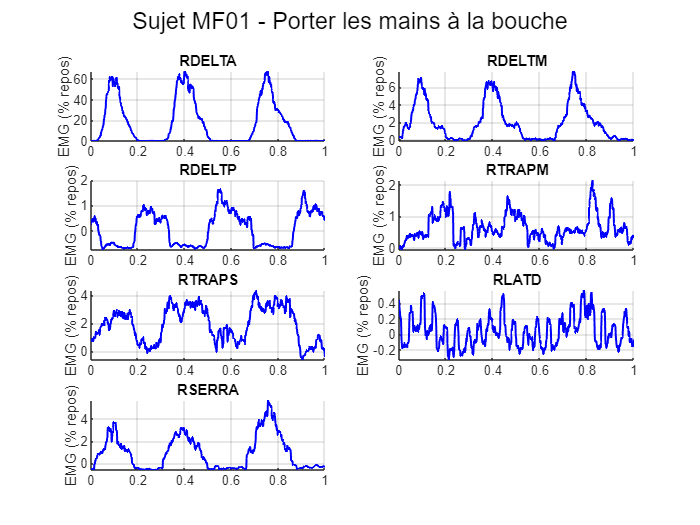

clc; clear all;

% Ajout de la bibliothèque btk  
addpath(genpath('C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\btk'));

% Définition des sujets
subjects = {'MF01'};
nb_subjects = length(subjects);

% Définition des muscles pour les côtés droit et gauche
muscles_R = {'RDELTA', 'RDELTM', 'RDELTP', 'RTRAPM', 'RTRAPS', 'RLATD', 'RSERRA'};
muscles_L = {'LDELTA', 'LDELTM', 'LDELTP', 'LTRAPM', 'LTRAPS', 'LLATD', 'LSERRA'};
nb_muscles = length(muscles_R);

% Définition des labels pour les tâches fonctionnelles
functional_labels = {
    'Porter les mains à la bouche', ...
    'Toucher le haut de la tête', ...
    'Porter les mains le plus haut possible au-dessus de la tête', ...
    'Porter les mains le plus haut possible le long de la colonne vertébrale'
};
nb_functional = length(functional_labels);

% Paramètres EMG
fs = 2000;
[b, a] = butter(4, [15, 475] / (fs/2), 'bandpass');
rms_window = round(0.250 * fs);
num_points = 1000;
time_normalized = linspace(0, 1, num_points);

% Initialisation des valeurs au repos
emg_rest = zeros(nb_muscles, 2, nb_subjects); % [muscles, côté, sujet]

% Extraction des signaux EMG au repos depuis CALIBRATION3
for subj_idx = 1:nb_subjects
    fileName_calibration = sprintf(['C:\\Users\\Francalanci Hugo\\Documents\\MATLAB\\Stage Sainte-Justine\\HUG\\Sujets\\%s\\' ...
        '%s-%s-20240101-PROTOCOL01-CALIBRATION3-.c3d'], ...
        subjects{subj_idx}, subjects{subj_idx}, subjects{subj_idx});
    
    if exist(fileName_calibration, 'file')
        c3dH_calibration = btkReadAcquisition(fileName_calibration);
        analogs_calibration = btkGetAnalogs(c3dH_calibration);
        
        for m = 1:nb_muscles
            for side = 1:2
                if side == 1
                    muscle_name = muscles_R{m};
                % else
                %     muscle_name = muscles_L{m};
                end
                
                if isfield(analogs_calibration, muscle_name)
                    signal = analogs_calibration.(muscle_name);
                    signal_filtered = filtfilt(b, a, signal);
                    emg_rms = sqrt(movmean(abs(signal_filtered).^2, rms_window));
                    emg_rest(m, side, subj_idx) = mean(emg_rms); % Moyenne de l'EMG au repos
                end
            end
        end
    else
        warning('Fichier CALIBRATION3 introuvable pour le sujet %s', subjects{subj_idx});
    end
end

% Sélection d'une tâche fonctionnelle unique
selected_functional = input('Choisissez une tâche fonctionnelle (1-4): ');

% Traitement des données EMG pour la tâche fonctionnelle
for subj_idx = 1:nb_subjects
    fileName_functional = sprintf(['C:\\Users\\Francalanci Hugo\\Documents\\MATLAB\\Stage Sainte-Justine\\HUG\\Sujets\\%s\\' ...
        '%s-%s-20240101-PROTOCOL01-FUNCTIONAL%d-.c3d'], ...
        subjects{subj_idx}, subjects{subj_idx}, subjects{subj_idx}, selected_functional);
    
    if exist(fileName_functional, 'file')
        c3dH_functional = btkReadAcquisition(fileName_functional);
        analogs_functional = btkGetAnalogs(c3dH_functional);
        
        figure;
        sgtitle(sprintf('Sujet %s - %s', subjects{subj_idx}, functional_labels{selected_functional}));
        
        for m = 1:nb_muscles
            subplot(ceil(nb_muscles/2), 2, m);
            hold on;
            
            for side = 1:2
                if side == 1
                    muscle_name = muscles_R{m};
                    color = 'b';
                % else
                %     muscle_name = muscles_L{m};
                %     color = 'r';
                end
                
                if isfield(analogs_functional, muscle_name)
                    signal = analogs_functional.(muscle_name);
                    signal_filtered = filtfilt(b, a, signal);
                    emg_rms = sqrt(movmean(abs(signal_filtered).^2, rms_window));

                    % Normalisation du temps
                    time_original = linspace(0, 1, length(emg_rms));
                    emg_interp = interp1(time_original, emg_rms, time_normalized, 'spline');

                    % Nouvelle normalisation basée sur le repos
                    if emg_rest(m, side, subj_idx) > 0
                        emg_normalized = ((((emg_interp - emg_rest(m, side, subj_idx)) / emg_rest(m, side, subj_idx)) * 100) ./100);
                    else
                        emg_normalized = emg_interp; % Si pas de repos mesuré, on laisse en valeurs absolues
                    end

                    plot(time_normalized, emg_normalized, color, 'LineWidth', 1.2);
                    title(muscle_name);
                    ylabel('EMG (% repos)');
                    grid on;
                else
                    title(sprintf('%s (Données absentes)', muscle_name));
                end
            end
        end
        hold off;
    else
        warning('Fichier introuvable : %s', fileName_functional);
    end
end